# Can You Bat .299 In 299 Games?

### FiveThirtyEight Puzzler Solution

Problem Statement: [https://fivethirtyeight.com/features/can-you-bat-299-in-299-games/](https://fivethirtyeight.com/features/can-you-bat-299-in-299-games/)

### Finding the largest number of games where Batting Average cannot equal Number of Games

Iterate through different numbers of games, calculate all possible batting averages, and check to see if there is a batting average euqal to the number of games. 500 seems like a safe number of games to check through, at that point there are 2000 at-bats so all 1001 possible batting averages should be well-covered.

mostGames = 0;
for numGames = 1:500
    numHits = 0:4*numGames;
    battingAverage = numHits./(4*numGames); % decimal in [0 1]
    battingAverage = round(1000*battingAverage); % integer in [0 1000]
    if ~any(battingAverage==numGames)
        mostGames = numGames;
    end
end
mostGames

mostGames =    239


### Validate Results by Calculating All Impossible Batting Averages 

Same approach as above, but this time store the intermediate results

A = zeros(500,1001); % Number of games x Batting average
for numGames = 1:500
    numHits = 0:4*numGames;
    battingAverage = numHits./(4*numGames);
    battingAverage = round(1000*battingAverage);
    A(numGames,battingAverage+1) = 1;
end

View the results

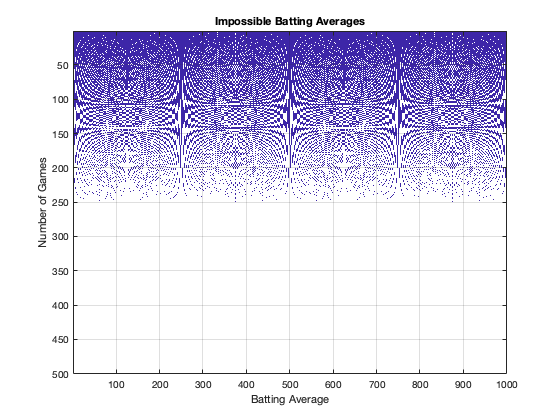

A(:,1) = []; % Remove "0" batting averages
figure
im = imagesc(A,'AlphaData',~A);
ylabel('Number of Games')
xlabel('Batting Average');
title('Impossible Batting Averages')
grid on

Add a line to the plot showing where number of games is equal to batting average.

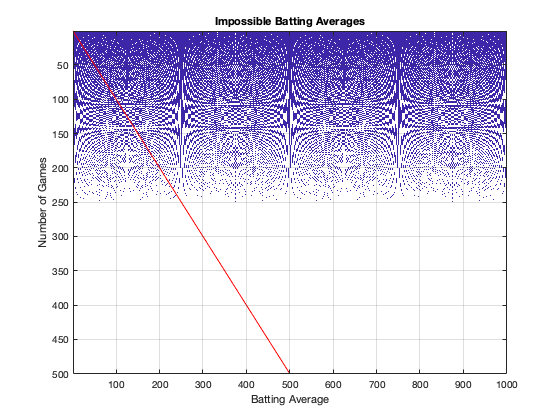

hold on
plot(0:500,0:500,'r')

Zoom in on the area around our solution. We see the last point where our line goes through an impossible batting average, at 239 games.

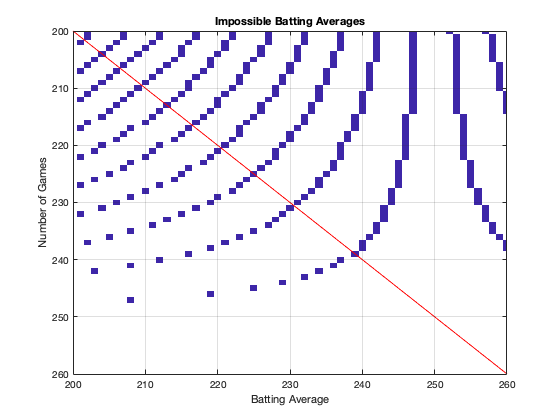

xlim([200 260])
ylim([200 260])